This is the first assignment for DSL810.

This code aims to study the trend in covid-19 cases of europe.

**Extracting data**

The data being used is from the John Hopkin university database. The code below maps all the paths for the different raw data sets and makes a list out of them.

disp('Running covid-19 data extraction code');

Running covid-19 data extraction code



datestr(now)

ans = '19-Nov-2020 13:00:06'


sessionstart=datetime('now');

tic
%defining global variables
global abspath datapath scriptpath datasetspath;

%path of the folder
abspath='/MATLAB Drive/';

%path for the raw data from SOOFA
datapath=strcat(abspath,'jhudata/');

%path where the scripts are kept
scriptpath=strcat(abspath,'assignment1/');

%path where the results are kept
datasetspath=strcat(abspath,'assignment1/datasets/');

addpath(scriptpath);
addpath(datapath);
addpath(datasetspath);

load covid19FileNames.mat;

This code appends all the data to a single table

s1numFiles=numel(s1allFileNames);

covid19_data=importfile2(strcat(datapath,s1allFileNames{1}));

for i = 2:s1numFiles

s1FileNamei=s1allFileNames{i};

covid19_data_onefile = importfile2(strcat(datapath,s1FileNamei));

covid19_data=vertcat(covid19_data,covid19_data_onefile);

end


covid19_data2 = convertvars(covid19_data,'Last_Update',@string);

%convert string to datetime variable in a Table
covid19_data2.Last_Update=datetime(covid19_data2.Last_Update,'InputFormat','yyyy-MM-dd HH:mm:ss');

% save('/MATLAB Drive/datasets/covid19_data2.mat','covid19_data2');

covid19_data2 now contains all the required data from the files. Now, we need to extract the data of only european countries. The countries in the data set are

countries = unique(covid19_data2(:,"Country_Region"))

countries = 190×1 table
      Country_Region   
    ___________________

    Afghanistan        
    Albania            
    Algeria            
    Andorra            
    Angola             
    Antigua and Barbuda
    Argentina          
    Armenia            
    Australia          
    Austria            
    Azerbaijan         
    Bahamas            
    Bahrain            
    Bangladesh         
    Barbados           
    Belarus            


Now the countries in europe union are:

- Austria

- Italy

- Belgium

- Latvia

- Bulgaria	

- Lithuania

- Croatia

- Luxembourg

- Cyprus

- Malta

- Czechia	

- Netherlands

- Denmark	

- Poland

- Estonia	

- Portugal

- Finland	

- Romania

- France	

- Slovakia

- Germany

- Slovenia

- Greece

- Spain

- Hungary

- Sweden

- Ireland

Thus, we extract the data of only these countries into another table:

%EU_countries= table(categorial{'Austria';'Italy';'Belgium';'Latvia';'Bulgaria';'Lithuania';'Croatia';'Luxembourg';'Cyprus';'Malta';'Czechia';'Netherlands';'Denmark';'Poland';'Estonia';'Portugal';'Finland';'Romania';'France';'Slovakia';'Germany';'Slovenia';'Greece';'Spain';'Hungary';'Sweden';'Ireland';'England'},{'Country_Region'})
%EU_countries = importfile3("/MATLAB Drive/assignment1/Eucountries.csv", [2, Inf])
%countries_data= covid19_data2(:,"Country_Region");
summary(covid19_data2)

Variables:

    Country_Region: 740000×1 categorical

        Values:

            Afghanistan                             202 
            Albania                                 202 
            Algeria                                 202 
            Andorra                                 202 
            Angola                                  202 
            Antigua and Barbuda                     202 
            Argentina                               202 
            Armenia                                 202 
            Australia                              1616 
            Austria                                 202 
            Azerbaijan                              202 
            Bahamas                                 202 
            Bahrain                                 202 
            Bangladesh                              202 
            Barbados                                202 
            Belarus                                 202 


countrywise_Austria = covid19_data2(covid19_data2.Country_Region=='Austria',:)

countrywise_Austria = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

       Austria        01-Apr-2020 21:58:34    47.5162    14.5501      10711       146        1436   
       Austria                         NaT    47.5162    14.5501      11129       158        1749   
       Austria        03-Apr-2020 22:46:20    47.5162    14.5501      11524       168        2022   
       Austria                         NaT    47.5162    14.5501      11781       186        2507   
       Austria        05-Apr-2020 23:06:26    47.5162    14.5501      12051       204        2998   
       Austria      

countrywise_Italy = covid19_data2(covid19_data2.Country_Region=='Italy',:)

countrywise_Italy = 3382×7 table
    Country_Region        Last_Update           Lat        Long_      Confirmed    Deaths    Recovered
    ______________    ____________________    ________    ________    _________    ______    _________

        Italy         01-Apr-2020 21:58:34    41.87194    12.56738     110574      13155       16847  
        Italy                          NaT    41.87194    12.56738     115242      13915       18278  
        Italy         03-Apr-2020 22:46:20    41.87194    12.56738     119827      14681       19758  
        Italy                          NaT    41.87194    12.56738     124632      15362       20996  
        Italy         05-Apr-2020 23:06:26    41.87194    12.56738     128948      15887       21815  
       

countrywise_Belgium = covid19_data2(covid19_data2.Country_Region=='Belgium',:)

countrywise_Belgium = 202×7 table
    Country_Region        Last_Update           Lat       Long_      Confirmed    Deaths    Recovered
    ______________    ____________________    _______    ________    _________    ______    _________

       Belgium        01-Apr-2020 21:58:34    50.8333    4.469936      13964        828       2132   
       Belgium                         NaT    50.8333    4.469936      15348       1011       2495   
       Belgium        03-Apr-2020 22:46:20    50.8333    4.469936      16770       1143       2872   
       Belgium                         NaT    50.8333    4.469936      18431       1283       3247   
       Belgium        05-Apr-2020 23:06:26    50.8333    4.469936      19691       1447       3751   
       Belgiu

countrywise_Latvia = covid19_data2(covid19_data2.Country_Region=='Latvia',:)

countrywise_Latvia = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

        Latvia        01-Apr-2020 21:58:34    56.8796    24.6032       446         0           1    
        Latvia                         NaT    56.8796    24.6032       458         0          31    
        Latvia        03-Apr-2020 22:46:20    56.8796    24.6032       493         1           1    
        Latvia                         NaT    56.8796    24.6032       509         1           1    
        Latvia        05-Apr-2020 23:06:26    56.8796    24.6032       533         1           1    
        Latvia       

countrywise_Bulgaria = covid19_data2(covid19_data2.Country_Region=='Bulgaria',:)

countrywise_Bulgaria = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

       Bulgaria       01-Apr-2020 21:58:34    42.7339    25.4858       422         10          20   
       Bulgaria                        NaT    42.7339    25.4858       457         10          25   
       Bulgaria       03-Apr-2020 22:46:20    42.7339    25.4858       485         14          30   
       Bulgaria                        NaT    42.7339    25.4858       503         17          34   
       Bulgaria       05-Apr-2020 23:06:26    42.7339    25.4858       531         20          37   
       Bulgaria    

countrywise_Lithuania = covid19_data2(covid19_data2.Country_Region=='Lithuania',:)

countrywise_Lithuania = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

      Lithuania       01-Apr-2020 21:58:34    55.1694    23.8813       581          8           7   
      Lithuania                        NaT    55.1694    23.8813       649          9           7   
      Lithuania       03-Apr-2020 22:46:20    55.1694    23.8813       696          9           7   
      Lithuania                        NaT    55.1694    23.8813       771         11           7   
      Lithuania       05-Apr-2020 23:06:26    55.1694    23.8813       811         13           7   
      Lithuania   

countrywise_Croatia = covid19_data2(covid19_data2.Country_Region=='Croatia',:)

countrywise_Croatia = 202×7 table
    Country_Region        Last_Update         Lat     Long_    Confirmed    Deaths    Recovered
    ______________    ____________________    ____    _____    _________    ______    _________

       Croatia        01-Apr-2020 21:58:34    45.1    15.2        963          6          73   
       Croatia                         NaT    45.1    15.2       1011          7          88   
       Croatia        03-Apr-2020 22:46:20    45.1    15.2       1079          8          92   
       Croatia                         NaT    45.1    15.2       1126         12         119   
       Croatia        05-Apr-2020 23:06:26    45.1    15.2       1182         15         125   
       Croatia                         NaT    45.1    1

countrywise_Luxembourg = covid19_data2(covid19_data2.Country_Region=='Luxembourg',:)

countrywise_Luxembourg = 202×7 table
    Country_Region        Last_Update           Lat      Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    ______    _________    ______    _________

      Luxembourg      01-Apr-2020 21:58:34    49.8153    6.1296      2319         29          80   
      Luxembourg                       NaT    49.8153    6.1296      2487         30          80   
      Luxembourg      03-Apr-2020 22:46:20    49.8153    6.1296      2612         31         500   
      Luxembourg                       NaT    49.8153    6.1296      2729         31         500   
      Luxembourg      05-Apr-2020 23:06:26    49.8153    6.1296      2804         36         500   
      Luxembourg        

countrywise_Cyprus = covid19_data2(covid19_data2.Country_Region=='Cyprus',:)

countrywise_Cyprus = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

        Cyprus        01-Apr-2020 21:58:34    35.1264    33.4299       320          9         28    
        Cyprus                         NaT    35.1264    33.4299       356         10         28    
        Cyprus        03-Apr-2020 22:46:20    35.1264    33.4299       396         11         28    
        Cyprus                         NaT    35.1264    33.4299       426         11         33    
        Cyprus        05-Apr-2020 23:06:26    35.1264    33.4299       446          9         37    
        Cyprus       

countrywise_Malta = covid19_data2(covid19_data2.Country_Region=='Malta',:)

countrywise_Malta = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

        Malta         01-Apr-2020 21:58:34    35.9375    14.3754       188         0           2    
        Malta                          NaT    35.9375    14.3754       196         0           2    
        Malta         03-Apr-2020 22:46:20    35.9375    14.3754       202         0           2    
        Malta                          NaT    35.9375    14.3754       213         0           2    
        Malta         05-Apr-2020 23:06:26    35.9375    14.3754       227         0           5    
        Malta         

countrywise_Czechia = covid19_data2(covid19_data2.Country_Region=='Czechia',:)

countrywise_Czechia = 202×7 table
    Country_Region        Last_Update           Lat      Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    ______    _________    ______    _________

       Czechia        01-Apr-2020 21:58:34    49.8175    15.473      3508         39          61   
       Czechia                         NaT    49.8175    15.473      3858         44          67   
       Czechia        03-Apr-2020 22:46:20    49.8175    15.473      4091         53          72   
       Czechia                         NaT    49.8175    15.473      4472         59          78   
       Czechia        05-Apr-2020 23:06:26    49.8175    15.473      4587         67          96   
       Czechia             

countrywise_Netherlands = covid19_data2(covid19_data2.Country_Region=='Netherlands',:)

countrywise_Netherlands = 2149×7 table
    Country_Region        Last_Update           Lat       Long_      Confirmed    Deaths    Recovered
    ______________    ____________________    _______    ________    _________    ______    _________

     Netherlands      01-Apr-2020 21:58:34    12.5211    -69.9683         55          0          1   
     Netherlands      01-Apr-2020 21:58:34    12.1696      -68.99         11          1          3   
     Netherlands      01-Apr-2020 21:58:34    18.0425    -63.0548         16          1          6   
     Netherlands      01-Apr-2020 21:58:34    52.1326      5.2913      13614       1173        250   
     Netherlands                       NaT    12.5211    -69.9683         60          0          1   
     Net

countrywise_Denmark = covid19_data2(covid19_data2.Country_Region=='Denmark',:)

countrywise_Denmark = 606×7 table
    Country_Region        Last_Update           Lat       Long_      Confirmed    Deaths    Recovered
    ______________    ____________________    _______    ________    _________    ______    _________

       Denmark        01-Apr-2020 21:58:34    61.8926     -6.9118       173          0          75   
       Denmark        01-Apr-2020 21:58:34    71.7069    -42.6043        10          0           2   
       Denmark        01-Apr-2020 21:58:34    56.2639      9.5018      3107        104         894   
       Denmark                         NaT    61.8926     -6.9118       177          0          81   
       Denmark                         NaT    71.7069    -42.6043        10          0           2   
       Denmar

countrywise_Poland = covid19_data2(covid19_data2.Country_Region=='Poland',:)

countrywise_Poland = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

        Poland        01-Apr-2020 21:58:34    51.9194    19.1451      2554         43          47   
        Poland                         NaT    51.9194    19.1451      2946         57          56   
        Poland        03-Apr-2020 22:46:20    51.9194    19.1451      3383         71          56   
        Poland                         NaT    51.9194    19.1451      3627         79         116   
        Poland        05-Apr-2020 23:06:26    51.9194    19.1451      4102         94         134   
        Poland       

countrywise_Estonia = covid19_data2(covid19_data2.Country_Region=='Estonia',:)

countrywise_Estonia = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

       Estonia        01-Apr-2020 21:58:34    58.5953    25.0136       779          5          33   
       Estonia                         NaT    58.5953    25.0136       858         11          45   
       Estonia        03-Apr-2020 22:46:20    58.5953    25.0136       961         12          48   
       Estonia                         NaT    58.5953    25.0136      1039         13          59   
       Estonia        05-Apr-2020 23:06:26    58.5953    25.0136      1097         15          62   
       Estonia      

countrywise_Portugal = covid19_data2(covid19_data2.Country_Region=='Portugal',:)

countrywise_Portugal = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

       Portugal       01-Apr-2020 21:58:34    39.3999    -8.2245       8251       187          43   
       Portugal                        NaT    39.3999    -8.2245       9034       209          68   
       Portugal       03-Apr-2020 22:46:20    39.3999    -8.2245       9886       246          68   
       Portugal                        NaT    39.3999    -8.2245      10524       266          75   
       Portugal       05-Apr-2020 23:06:26    39.3999    -8.2245      11278       295          75   
       Portugal    

countrywise_Finland = covid19_data2(covid19_data2.Country_Region=='Finland',:)

countrywise_Finland = 202×7 table
    Country_Region        Last_Update           Lat         Long_      Confirmed    Deaths    Recovered
    ______________    ____________________    ________    _________    _________    ______    _________

       Finland        01-Apr-2020 21:58:34    61.92411    25.748151      1446         17          10   
       Finland                         NaT    61.92411    25.748151      1518         19         300   
       Finland        03-Apr-2020 22:46:20    61.92411    25.748151      1615         20         300   
       Finland                         NaT    61.92411    25.748151      1882         25         300   
       Finland        05-Apr-2020 23:06:26    61.92411    25.748151      1927         28         300   

countrywise_Romania = covid19_data2(covid19_data2.Country_Region=='Romania',:)

countrywise_Romania = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

       Romania        01-Apr-2020 21:58:34    45.9432    24.9668      2460         92         252   
       Romania                         NaT    45.9432    24.9668      2738        115         267   
       Romania        03-Apr-2020 22:46:20    45.9432    24.9668      3183        133         283   
       Romania                         NaT    45.9432    24.9668      3613        146         329   
       Romania        05-Apr-2020 23:06:26    45.9432    24.9668      3864        151         374   
       Romania      

countrywise_France = covid19_data2(covid19_data2.Country_Region=='France',:)

countrywise_France = 2218×7 table
    Country_Region        Last_Update            Lat          Long_       Confirmed    Deaths    Recovered
    ______________    ____________________    __________    __________    _________    ______    _________

        France        01-Apr-2020 21:58:34             4           -53         51          0          15  
        France        01-Apr-2020 21:58:34      -17.6797     -149.4068         37          0           0  
        France        01-Apr-2020 21:58:34        16.265       -61.551        125          6          24  
        France        01-Apr-2020 21:58:34       14.6415      -61.0242        135          3          27  
        France        01-Apr-2020 21:58:34      -12.8275     45.166244         94    

countrywise_Slovakia = covid19_data2(covid19_data2.Country_Region=='Slovakia',:)

countrywise_Slovakia = 202×7 table
    Country_Region        Last_Update          Lat      Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    ______    ______    _________    ______    _________

       Slovakia       01-Apr-2020 21:58:34    48.669    19.699       400         1            3   
       Slovakia                        NaT    48.669    19.699       426         1            5   
       Slovakia       03-Apr-2020 22:46:20    48.669    19.699       450         1           10   
       Slovakia                        NaT    48.669    19.699       471         1           10   
       Slovakia       05-Apr-2020 23:06:26    48.669    19.699       485         1           10   
       Slovakia                  

countrywise_Germany = covid19_data2(covid19_data2.Country_Region=='Germany',:)

countrywise_Germany = 2746×7 table
    Country_Region        Last_Update            Lat         Long_      Confirmed    Deaths    Recovered
    ______________    ____________________    _________    _________    _________    ______    _________

       Germany        01-Apr-2020 21:58:34    51.165691    10.451526      77872        920       18700  
       Germany                         NaT    51.165691    10.451526      84794       1107       22440  
       Germany        03-Apr-2020 22:46:20    51.165691    10.451526      91159       1275       24575  
       Germany                         NaT    51.165691    10.451526      96092       1444       26400  
       Germany        05-Apr-2020 23:06:26    51.165691    10.451526     100123       1584      

countrywise_Slovenia = covid19_data2(covid19_data2.Country_Region=='Slovenia',:)

countrywise_Slovenia = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

       Slovenia       01-Apr-2020 21:58:34    46.1512    14.9955       841         15          10   
       Slovenia                        NaT    46.1512    14.9955       897         17          70   
       Slovenia       03-Apr-2020 22:46:20    46.1512    14.9955       934         20          70   
       Slovenia                        NaT    46.1512    14.9955       977         22          79   
       Slovenia       05-Apr-2020 23:06:26    46.1512    14.9955       997         28          79   
       Slovenia    

countrywise_Greece = covid19_data2(covid19_data2.Country_Region=='Greece',:)

countrywise_Greece = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

        Greece        01-Apr-2020 21:58:34    39.0742    21.8243      1415         50          52   
        Greece                         NaT    39.0742    21.8243      1544         53          61   
        Greece        03-Apr-2020 22:46:20    39.0742    21.8243      1613         63          78   
        Greece                         NaT    39.0742    21.8243      1673         68          78   
        Greece        05-Apr-2020 23:06:26    39.0742    21.8243      1735         73          78   
        Greece       

countrywise_Spain = covid19_data2(covid19_data2.Country_Region=='Spain',:)

countrywise_Spain = 3218×7 table
    Country_Region        Last_Update            Lat        Long_      Confirmed    Deaths    Recovered
    ______________    ____________________    _________    ________    _________    ______    _________

        Spain         01-Apr-2020 21:58:34    40.463667    -3.74922     104118       9387       22647  
        Spain                          NaT    40.463667    -3.74922     112065      10348       26743  
        Spain         03-Apr-2020 22:46:20    40.463667    -3.74922     119199      11198       30513  
        Spain                          NaT    40.463667    -3.74922     126168      11947       34219  
        Spain         05-Apr-2020 23:06:26    40.463667    -3.74922     131646      12641       38080  


countrywise_Hungary = covid19_data2(covid19_data2.Country_Region=='Hungary',:)

countrywise_Hungary = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

       Hungary        01-Apr-2020 21:58:34    47.1625    19.5033       525         20          40   
       Hungary                         NaT    47.1625    19.5033       585         21          42   
       Hungary        03-Apr-2020 22:46:20    47.1625    19.5033       623         26          43   
       Hungary                         NaT    47.1625    19.5033       678         32          58   
       Hungary        05-Apr-2020 23:06:26    47.1625    19.5033       733         34          66   
       Hungary      

countrywise_Sweden = covid19_data2(covid19_data2.Country_Region=='Sweden',:)

countrywise_Sweden = 2942×7 table
    Country_Region        Last_Update            Lat         Long_      Confirmed    Deaths    Recovered
    ______________    ____________________    _________    _________    _________    ______    _________

        Sweden        01-Apr-2020 21:58:34    60.128161    18.643501       4947        239        103   
        Sweden                         NaT    60.128161    18.643501       5568        308        103   
        Sweden        03-Apr-2020 22:46:20    60.128161    18.643501       6131        358        205   
        Sweden                         NaT    60.128161    18.643501       6443        373        205   
        Sweden        05-Apr-2020 23:06:26    60.128161    18.643501       6830        401       

countrywise_Ireland = covid19_data2(covid19_data2.Country_Region=='Ireland',:)

countrywise_Ireland = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

       Ireland        01-Apr-2020 21:58:34    53.1424    -7.6921       3447        85          5    
       Ireland                         NaT    53.1424    -7.6921       3849        98          5    
       Ireland        03-Apr-2020 22:46:20    53.1424    -7.6921       4273       120          5    
       Ireland                         NaT    53.1424    -7.6921       4604       137         25    
       Ireland        05-Apr-2020 23:06:26    53.1424    -7.6921       4994       158         25    
       Ireland      

The database consists of entries with no last update assigned to them. Thus, we assume that the entry was made in between the preceeding and succesive entry. Thus, the corrected datasets are-

countrywise_Austria=cleanUpdates(countrywise_Austria);

n =    202


countrywise_Italy=cleanUpdates(countrywise_Italy);

n =         3382


countrywise_Belgium=cleanUpdates(countrywise_Belgium);

n =    202


countrywise_Latvia=cleanUpdates(countrywise_Latvia);

n =    202


countrywise_Bulgaria=cleanUpdates(countrywise_Bulgaria);

n =    202


countrywise_Lithuania=cleanUpdates(countrywise_Lithuania);

n =    202


countrywise_Croatia=cleanUpdates(countrywise_Croatia);

n =    202


countrywise_Luxembourg=cleanUpdates(countrywise_Luxembourg);

n =    202


countrywise_Cyprus=cleanUpdates(countrywise_Cyprus);

n =    202


countrywise_Malta=cleanUpdates(countrywise_Malta);

n =    202


countrywise_Czechia=cleanUpdates(countrywise_Czechia);

n =    202


countrywise_Netherlands=cleanUpdates(countrywise_Netherlands);

n =         2149


countrywise_Denmark=cleanUpdates(countrywise_Denmark);

n =    606


countrywise_Poland=cleanUpdates(countrywise_Poland);

n =    202


countrywise_Estonia=cleanUpdates(countrywise_Estonia);

n =    202


countrywise_Portugal=cleanUpdates(countrywise_Portugal);

n =    202


countrywise_Finland= cleanUpdates(countrywise_Finland);

n =    202


countrywise_Romania =cleanUpdates(countrywise_Romania);

n =    202


countrywise_France=cleanUpdates(countrywise_France);

n =         2218


countrywise_Slovakia =cleanUpdates(countrywise_Slovakia);

n =    202


countrywise_Germany=cleanUpdates(countrywise_Germany);

n =         2746


countrywise_Slovenia=cleanUpdates(countrywise_Slovenia);

n =    202


countrywise_Greece=cleanUpdates(countrywise_Greece);

n =    202


countrywise_Spain=cleanUpdates(countrywise_Spain);

n =         3218


countrywise_Hungary=cleanUpdates(countrywise_Hungary);

n =    202


countrywise_Sweden=cleanUpdates(countrywise_Sweden);

n =         2942


countrywise_Ireland=cleanUpdates(countrywise_Ireland);

n =    202


Now, the graph paramrters have to be derived-

fcountrywise_Austria= graphparam(countrywise_Austria)

fcountrywise_Austria = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

       Austria        01-Apr-2020 21:58:34    47.5162    14.5501      10711       146        1436       9129
       Austria        03-Apr-2020 22:46:20    47.5162    14.5501      11129       158        1749         93
       Austria        03-Apr-2020 22:46:20    47.5162    14.5501      11524       168        2022        112
       Austria        05-Apr-2020 23:06:26    47.5162    14.5501      11781       186        2507       -246
       Austria        05-Apr-2020 23:0

fcountrywise_Italy=graphparam(countrywise_Italy)

fcountrywise_Italy = 3382×8 table
    Country_Region        Last_Update           Lat        Long_      Confirmed    Deaths    Recovered    Var1 
    ______________    ____________________    ________    ________    _________    ______    _________    _____

        Italy         01-Apr-2020 21:58:34    41.87194    12.56738     110574      13155       16847      80572
        Italy         03-Apr-2020 22:46:20    41.87194    12.56738     115242      13915       18278       2477
        Italy         03-Apr-2020 22:46:20    41.87194    12.56738     119827      14681       19758       2339
        Italy         05-Apr-2020 23:06:26    41.87194    12.56738     124632      15362       20996       2886
        Italy        

fcountrywise_Belgium=graphparam(countrywise_Belgium)

fcountrywise_Belgium = 202×8 table
    Country_Region        Last_Update           Lat       Long_      Confirmed    Deaths    Recovered    Var1 
    ______________    ____________________    _______    ________    _________    ______    _________    _____

       Belgium        01-Apr-2020 21:58:34    50.8333    4.469936      13964        828       2132       11004
       Belgium        03-Apr-2020 22:46:20    50.8333    4.469936      15348       1011       2495         838
       Belgium        03-Apr-2020 22:46:20    50.8333    4.469936      16770       1143       2872         913
       Belgium        05-Apr-2020 23:06:26    50.8333    4.469936      18431       1283       3247        1146
       Belgium        05-A

fcountrywise_Latvia=graphparam(countrywise_Latvia)

fcountrywise_Latvia = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

        Latvia        01-Apr-2020 21:58:34    56.8796    24.6032       446         0           1        445 
        Latvia        03-Apr-2020 22:46:20    56.8796    24.6032       458         0          31        -18 
        Latvia        03-Apr-2020 22:46:20    56.8796    24.6032       493         1           1         64 
        Latvia        05-Apr-2020 23:06:26    56.8796    24.6032       509         1           1         16 
        Latvia        05-Apr-2020 23:06

fcountrywise_Bulgaria=graphparam(countrywise_Bulgaria)

fcountrywise_Bulgaria = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

       Bulgaria       01-Apr-2020 21:58:34    42.7339    25.4858       422         10          20       392 
       Bulgaria       03-Apr-2020 22:46:20    42.7339    25.4858       457         10          25        30 
       Bulgaria       03-Apr-2020 22:46:20    42.7339    25.4858       485         14          30        19 
       Bulgaria       05-Apr-2020 23:06:26    42.7339    25.4858       503         17          34        11 
       Bulgaria       05-Apr-2020 23:

fcountrywise_Lithuania=graphparam(countrywise_Lithuania)

fcountrywise_Lithuania = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

      Lithuania       01-Apr-2020 21:58:34    55.1694    23.8813       581          8           7       566 
      Lithuania       03-Apr-2020 22:46:20    55.1694    23.8813       649          9           7        67 
      Lithuania       03-Apr-2020 22:46:20    55.1694    23.8813       696          9           7        47 
      Lithuania       05-Apr-2020 23:06:26    55.1694    23.8813       771         11           7        73 
      Lithuania       05-Apr-2020 23

fcountrywise_Croatia=graphparam(countrywise_Croatia)

fcountrywise_Croatia = 202×8 table
    Country_Region        Last_Update         Lat     Long_    Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    ____    _____    _________    ______    _________    ____

       Croatia        01-Apr-2020 21:58:34    45.1    15.2        963          6          73       884 
       Croatia        03-Apr-2020 22:46:20    45.1    15.2       1011          7          88        32 
       Croatia        03-Apr-2020 22:46:20    45.1    15.2       1079          8          92        63 
       Croatia        05-Apr-2020 23:06:26    45.1    15.2       1126         12         119        16 
       Croatia        05-Apr-2020 23:06:26    45.1    15.2       118

fcountrywise_Luxembourg=graphparam(countrywise_Luxembourg)

fcountrywise_Luxembourg = 202×8 table
    Country_Region        Last_Update           Lat      Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    ______    _________    ______    _________    ____

      Luxembourg      01-Apr-2020 21:58:34    49.8153    6.1296      2319         29          80       2210
      Luxembourg      03-Apr-2020 22:46:20    49.8153    6.1296      2487         30          80        167
      Luxembourg      03-Apr-2020 22:46:20    49.8153    6.1296      2612         31         500       -296
      Luxembourg      05-Apr-2020 23:06:26    49.8153    6.1296      2729         31         500        117
      Luxembourg      05-Apr-2020 23:06:2

fcountrywise_Cyprus=graphparam(countrywise_Cyprus)

fcountrywise_Cyprus = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

        Cyprus        01-Apr-2020 21:58:34    35.1264    33.4299       320          9         28        283 
        Cyprus        03-Apr-2020 22:46:20    35.1264    33.4299       356         10         28         35 
        Cyprus        03-Apr-2020 22:46:20    35.1264    33.4299       396         11         28         39 
        Cyprus        05-Apr-2020 23:06:26    35.1264    33.4299       426         11         33         25 
        Cyprus        05-Apr-2020 23:06

fcountrywise_Malta=graphparam(countrywise_Malta)

fcountrywise_Malta = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

        Malta         01-Apr-2020 21:58:34    35.9375    14.3754       188         0           2        186 
        Malta         03-Apr-2020 22:46:20    35.9375    14.3754       196         0           2          8 
        Malta         03-Apr-2020 22:46:20    35.9375    14.3754       202         0           2          6 
        Malta         05-Apr-2020 23:06:26    35.9375    14.3754       213         0           2         11 
        Malta         05-Apr-2020 23:06:

fcountrywise_Czechia=graphparam(countrywise_Czechia)

fcountrywise_Czechia = 202×8 table
    Country_Region        Last_Update           Lat      Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    ______    _________    ______    _________    ____

       Czechia        01-Apr-2020 21:58:34    49.8175    15.473      3508         39          61       3408
       Czechia        03-Apr-2020 22:46:20    49.8175    15.473      3858         44          67        339
       Czechia        03-Apr-2020 22:46:20    49.8175    15.473      4091         53          72        219
       Czechia        05-Apr-2020 23:06:26    49.8175    15.473      4472         59          78        369
       Czechia        05-Apr-2020 23:06:26  

fcountrywise_Netherlands=graphparam(countrywise_Netherlands)

fcountrywise_Netherlands = 2149×8 table
    Country_Region        Last_Update           Lat       Long_      Confirmed    Deaths    Recovered     Var1 
    ______________    ____________________    _______    ________    _________    ______    _________    ______

     Netherlands      01-Apr-2020 21:58:34    12.5211    -69.9683         55          0          1           54
     Netherlands      01-Apr-2020 21:58:34    12.1696      -68.99         11          1          3          -47
     Netherlands      01-Apr-2020 21:58:34    18.0425    -63.0548         16          1          6            2
     Netherlands      01-Apr-2020 21:58:34    52.1326      5.2913      13614       1173        250        12182
     Netherland

fcountrywise_Denmark=graphparam(countrywise_Denmark)

fcountrywise_Denmark = 606×8 table
    Country_Region        Last_Update           Lat       Long_      Confirmed    Deaths    Recovered    Var1 
    ______________    ____________________    _______    ________    _________    ______    _________    _____

       Denmark        01-Apr-2020 21:58:34    61.8926     -6.9118       173          0          75          98
       Denmark        01-Apr-2020 21:58:34    71.7069    -42.6043        10          0           2         -90
       Denmark        01-Apr-2020 21:58:34    56.2639      9.5018      3107        104         894        2101
       Denmark        01-Apr-2020 21:58:34    61.8926     -6.9118       177          0          81       -2013
       Denmark        01-A

fcountrywise_Poland=graphparam(countrywise_Poland)

fcountrywise_Poland = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

        Poland        01-Apr-2020 21:58:34    51.9194    19.1451      2554         43          47       2464
        Poland        03-Apr-2020 22:46:20    51.9194    19.1451      2946         57          56        369
        Poland        03-Apr-2020 22:46:20    51.9194    19.1451      3383         71          56        423
        Poland        05-Apr-2020 23:06:26    51.9194    19.1451      3627         79         116        176
        Poland        05-Apr-2020 23:06

fcountrywise_Estonia=graphparam(countrywise_Estonia)

fcountrywise_Estonia = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

       Estonia        01-Apr-2020 21:58:34    58.5953    25.0136       779          5          33       741 
       Estonia        03-Apr-2020 22:46:20    58.5953    25.0136       858         11          45        61 
       Estonia        03-Apr-2020 22:46:20    58.5953    25.0136       961         12          48        99 
       Estonia        05-Apr-2020 23:06:26    58.5953    25.0136      1039         13          59        66 
       Estonia        05-Apr-2020 23:0

fcountrywise_Portugal=graphparam(countrywise_Portugal)

fcountrywise_Portugal = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

       Portugal       01-Apr-2020 21:58:34    39.3999    -8.2245       8251       187          43       8021
       Portugal       03-Apr-2020 22:46:20    39.3999    -8.2245       9034       209          68        736
       Portugal       03-Apr-2020 22:46:20    39.3999    -8.2245       9886       246          68        815
       Portugal       05-Apr-2020 23:06:26    39.3999    -8.2245      10524       266          75        611
       Portugal       05-Apr-2020 23:

fcountrywise_Finland= graphparam(countrywise_Finland)

fcountrywise_Finland = 202×8 table
    Country_Region        Last_Update           Lat         Long_      Confirmed    Deaths    Recovered    Var1 
    ______________    ____________________    ________    _________    _________    ______    _________    _____

       Finland        01-Apr-2020 21:58:34    61.92411    25.748151      1446         17          10        1419
       Finland        03-Apr-2020 22:46:20    61.92411    25.748151      1518         19         300        -220
       Finland        03-Apr-2020 22:46:20    61.92411    25.748151      1615         20         300          96
       Finland        05-Apr-2020 23:06:26    61.92411    25.748151      1882         25         300         262
       Finland

fcountrywise_Romania =graphparam(countrywise_Romania)

fcountrywise_Romania = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

       Romania        01-Apr-2020 21:58:34    45.9432    24.9668      2460         92         252       2116
       Romania        03-Apr-2020 22:46:20    45.9432    24.9668      2738        115         267        240
       Romania        03-Apr-2020 22:46:20    45.9432    24.9668      3183        133         283        411
       Romania        05-Apr-2020 23:06:26    45.9432    24.9668      3613        146         329        371
       Romania        05-Apr-2020 23:0

fcountrywise_France=graphparam(countrywise_France)

fcountrywise_France = 2218×8 table
    Country_Region        Last_Update            Lat          Long_       Confirmed    Deaths    Recovered     Var1 
    ______________    ____________________    __________    __________    _________    ______    _________    ______

        France        01-Apr-2020 21:58:34             4           -53         51          0          15          36
        France        01-Apr-2020 21:58:34      -17.6797     -149.4068         37          0           0           1
        France        01-Apr-2020 21:58:34        16.265       -61.551        125          6          24          58
        France        01-Apr-2020 21:58:34       14.6415      -61.0242        135          3          27   

fcountrywise_Slovakia =graphparam(countrywise_Slovakia)

fcountrywise_Slovakia = 202×8 table
    Country_Region        Last_Update          Lat      Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    ______    ______    _________    ______    _________    ____

       Slovakia       01-Apr-2020 21:58:34    48.669    19.699       400         1            3       396 
       Slovakia       03-Apr-2020 22:46:20    48.669    19.699       426         1            5        24 
       Slovakia       03-Apr-2020 22:46:20    48.669    19.699       450         1           10        19 
       Slovakia       05-Apr-2020 23:06:26    48.669    19.699       471         1           10        21 
       Slovakia       05-Apr-2020 23:06:26    48.

fcountrywise_Germany=graphparam(countrywise_Germany)

fcountrywise_Germany = 2746×8 table
    Country_Region        Last_Update            Lat         Long_      Confirmed    Deaths    Recovered    Var1 
    ______________    ____________________    _________    _________    _________    ______    _________    _____

       Germany        01-Apr-2020 21:58:34    51.165691    10.451526      77872        920       18700      58252
       Germany        03-Apr-2020 22:46:20    51.165691    10.451526      84794       1107       22440       2995
       Germany        03-Apr-2020 22:46:20    51.165691    10.451526      91159       1275       24575       4062
       Germany        05-Apr-2020 23:06:26    51.165691    10.451526      96092       1444       26400       2939
       

fcountrywise_Slovenia=graphparam(countrywise_Slovenia)

fcountrywise_Slovenia = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

       Slovenia       01-Apr-2020 21:58:34    46.1512    14.9955       841         15          10       816 
       Slovenia       03-Apr-2020 22:46:20    46.1512    14.9955       897         17          70        -6 
       Slovenia       03-Apr-2020 22:46:20    46.1512    14.9955       934         20          70        34 
       Slovenia       05-Apr-2020 23:06:26    46.1512    14.9955       977         22          79        32 
       Slovenia       05-Apr-2020 23:

fcountrywise_Greece=cleanUpdates(countrywise_Greece)

n =    202


fcountrywise_Greece = 202×7 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered
    ______________    ____________________    _______    _______    _________    ______    _________

        Greece        01-Apr-2020 21:58:34    39.0742    21.8243      1415         50          52   
        Greece        03-Apr-2020 22:46:20    39.0742    21.8243      1544         53          61   
        Greece        03-Apr-2020 22:46:20    39.0742    21.8243      1613         63          78   
        Greece        05-Apr-2020 23:06:26    39.0742    21.8243      1673         68          78   
        Greece        05-Apr-2020 23:06:26    39.0742    21.8243      1735         73          78   
        Greece      

fcountrywise_Spain=graphparam(countrywise_Spain)

fcountrywise_Spain = 3218×8 table
    Country_Region        Last_Update            Lat        Long_      Confirmed    Deaths    Recovered    Var1 
    ______________    ____________________    _________    ________    _________    ______    _________    _____

        Spain         01-Apr-2020 21:58:34    40.463667    -3.74922     104118       9387       22647      72084
        Spain         03-Apr-2020 22:46:20    40.463667    -3.74922     112065      10348       26743       2890
        Spain         03-Apr-2020 22:46:20    40.463667    -3.74922     119199      11198       30513       2514
        Spain         05-Apr-2020 23:06:26    40.463667    -3.74922     126168      11947       34219       2514
        Spain  

fcountrywise_Hungary=graphparam(countrywise_Hungary)

fcountrywise_Hungary = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

       Hungary        01-Apr-2020 21:58:34    47.1625    19.5033       525         20          40       465 
       Hungary        03-Apr-2020 22:46:20    47.1625    19.5033       585         21          42        57 
       Hungary        03-Apr-2020 22:46:20    47.1625    19.5033       623         26          43        32 
       Hungary        05-Apr-2020 23:06:26    47.1625    19.5033       678         32          58        34 
       Hungary        05-Apr-2020 23:0

fcountrywise_Sweden=graphparam(countrywise_Sweden)

fcountrywise_Sweden = 2942×8 table
    Country_Region        Last_Update            Lat         Long_      Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _________    _________    _________    ______    _________    ____

        Sweden        01-Apr-2020 21:58:34    60.128161    18.643501       4947        239        103       4605
        Sweden        03-Apr-2020 22:46:20    60.128161    18.643501       5568        308        103        552
        Sweden        03-Apr-2020 22:46:20    60.128161    18.643501       6131        358        205        411
        Sweden        05-Apr-2020 23:06:26    60.128161    18.643501       6443        373        205        297
        Sweden

fcountrywise_Ireland=graphparam(countrywise_Ireland)

fcountrywise_Ireland = 202×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

       Ireland        01-Apr-2020 21:58:34    53.1424    -7.6921       3447        85          5        3357
       Ireland        03-Apr-2020 22:46:20    53.1424    -7.6921       3849        98          5         389
       Ireland        03-Apr-2020 22:46:20    53.1424    -7.6921       4273       120          5         402
       Ireland        05-Apr-2020 23:06:26    53.1424    -7.6921       4604       137         25         294
       Ireland        05-Apr-2020 23:0


%plot(fcountrywise_Austria.Last_Update, fcountrywise_Austria.Var1)
Eu_database = [fcountrywise_Austria;fcountrywise_Italy;fcountrywise_Belgium;fcountrywise_Latvia;fcountrywise_Bulgaria;fcountrywise_Lithuania;fcountrywise_Croatia;fcountrywise_Luxembourg;fcountrywise_Cyprus;fcountrywise_Malta;fcountrywise_Czechia;fcountrywise_Netherlands;fcountrywise_Denmark;fcountrywise_Poland;fcountrywise_Estonia;fcountrywise_Portugal;fcountrywise_Finland;fcountrywise_Croatia]

Eu_database = 9167×8 table
    Country_Region        Last_Update           Lat       Long_     Confirmed    Deaths    Recovered    Var1
    ______________    ____________________    _______    _______    _________    ______    _________    ____

       Austria        01-Apr-2020 21:58:34    47.5162    14.5501      10711       146        1436       9129
       Austria        03-Apr-2020 22:46:20    47.5162    14.5501      11129       158        1749         93
       Austria        03-Apr-2020 22:46:20    47.5162    14.5501      11524       168        2022        112
       Austria        05-Apr-2020 23:06:26    47.5162    14.5501      11781       186        2507       -246
       Austria        05-Apr-2020 23:06:26    


Eu_database = sortrows(Eu_database,'Last_Update')

Eu_database = 9167×8 table
    Country_Region        Last_Update           Lat        Long_      Confirmed    Deaths    Recovered     Var1 
    ______________    ____________________    ________    ________    _________    ______    _________    ______

     Austria          01-Apr-2020 21:58:34     47.5162     14.5501      10711        146        1436        9129
     Italy            01-Apr-2020 21:58:34    41.87194    12.56738     110574      13155       16847       80572
     Belgium          01-Apr-2020 21:58:34     50.8333    4.469936      13964        828        2132       11004
     Latvia           01-Apr-2020 21:58:34     56.8796     24.6032        446          0           1         445
     Bulgaria         


%plot(countrywise_Austria.Last_Update,(countrywise_Austria.Confirmed - countrywise_Austria.Deaths - countrywise_Austria.Recovered))

Now that we have the variations taking place in the data stored in Var1, we only need to add these variations cummilatively to get the desired visualization.

h=height(Eu_database);
x=table(zeros(h,1),'VariableNames',{'Cases_Active'});
Eu_database_final=[Eu_database,x]

Eu_database_final = 9167×9 table
    Country_Region        Last_Update           Lat        Long_      Confirmed    Deaths    Recovered     Var1     Cases_Active
    ______________    ____________________    ________    ________    _________    ______    _________    ______    ____________

     Austria          01-Apr-2020 21:58:34     47.5162     14.5501      10711        146        1436        9129         0      
     Italy            01-Apr-2020 21:58:34    41.87194    12.56738     110574      13155       16847       80572         0      
     Belgium          01-Apr-2020 21:58:34     50.8333    4.469936      13964        828        2132       11004         0      
     Latvia    


Eu_database_final.Cases_Active(1)=Eu_database_final.Var1(1);

for i=2:h
    Eu_database_final.Cases_Active(i)=Eu_database_final.Cases_Active(i-1)+Eu_database_final.Var1(i);
end
Eu_database_final

Eu_database_final = 9167×9 table
    Country_Region        Last_Update           Lat        Long_      Confirmed    Deaths    Recovered     Var1     Cases_Active
    ______________    ____________________    ________    ________    _________    ______    _________    ______    ____________

     Austria          01-Apr-2020 21:58:34     47.5162     14.5501      10711        146        1436        9129         9129   
     Italy            01-Apr-2020 21:58:34    41.87194    12.56738     110574      13155       16847       80572        89701   
     Belgium          01-Apr-2020 21:58:34     50.8333    4.469936      13964        828        2132       11004       100705   
     Latvia    

Finally, we plot the graph for Europe with time:

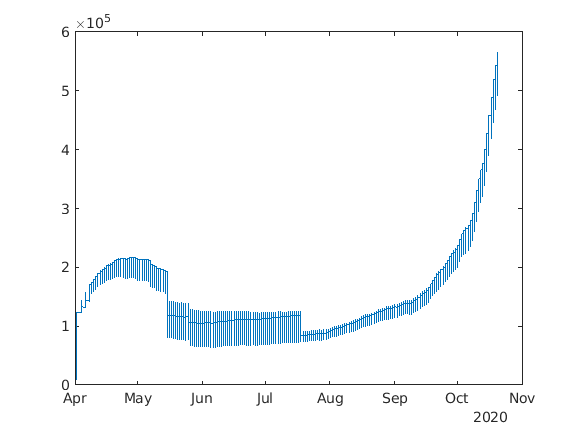

plot(Eu_database_final.Last_Update,Eu_database_final.Cases_Active)

Just for easiy visualization, the following data is smoothened to give a better curve.

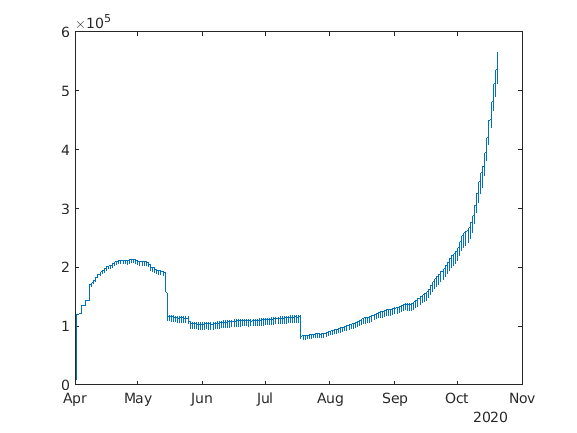

y=smooth(Eu_database_final.Cases_Active);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
y=smooth(y);
plot(Eu_database_final.Last_Update,y)

Thus, we can observe that Europe was hit by a second wave of Covid-19.